% Resistance estimation

% Datapoints: write what you measure
% NB: we need column vectors
V = [0.8  1.52 2.06 2.39 1.18 1    3.23 3.40 4.15 4.80 5.05 5.48]';
I = [0.24 0.47 0.68 0.82 0.40 0.33 1.11 1.22 1.50 1.73 1.81 1.97]';

save("resistance.mat", "V", "I")

% Mean resistance
R_mean = V ./ I;
R_mean = mean(R_mean)

R_mean = 2.9418


% Linear regression
R_regr = 1 / (V \ I)

R_regr = 2.8156

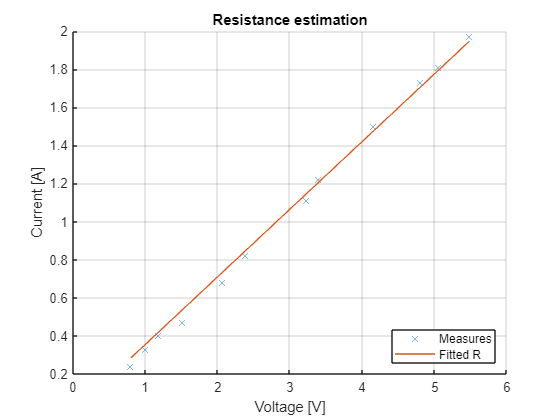


figure;
hold on; 
plot(V, I, 'x');
%plot(V, V/R_mean);
plot(V, V/R_regr);
legend("Measures", "Fitted R", 'location', 'southeast')
grid on;
xlabel("Voltage [V]")
ylabel("Current [A]")
title("Resistance estimation")

% Flux constant estimation

R = R_regr;
k_true = 3; %Just for the example

% Datapoints: write what you measure
% NB: we need column vectors
V = [5 6.1 7 4 3.5 4.5 5.5 6.45]';
w = [136 169 197 107 88 119 149 180]';
I = 0.17 % [0.17 0.17 0.18 0.17 0.17 0.17 0.17 0.18]';

I = 0.1700


save("flux_constant.mat", "V", "w", "I")


% NB: here phi and Phi are the simbols of the linear regression, not the
% flux
% The flux constant is k
% Mean
phi = (V - I*R) ./ w;
k_mean = mean(phi)

k_mean = 0.0334


% Linear Regression
k_regr = 1/ ( (V - I*R) \ w )

k_regr = 0.0333

sort(V)

ans =     3.5000
    4.0000
    4.5000
    5.0000
    5.5000
    6.1000
    6.4500
    7.0000


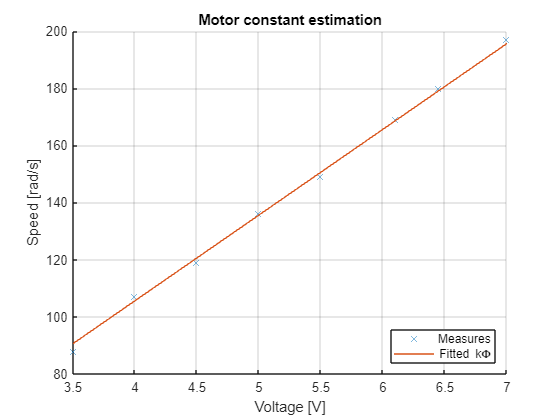


figure;
hold on;
plot(V, w, 'x');
%plot(V, (V-R*I)/k_mean );
plot(V, (V-R*I)/k_regr );
legend("Measures", "Fitted k\Phi", 'location', 'southeast')
grid on;
xlabel("Voltage [V]")
ylabel("Speed [rad/s]")
title("Motor constant estimation")

% Inertia estimation

% Positive step
load step.mat

y_ss = mean(y( length(y)/2:length(y)))

y_ss = 283.1006

y_ss_63 = 0.63 * y_ss

y_ss_63 = 178.3534

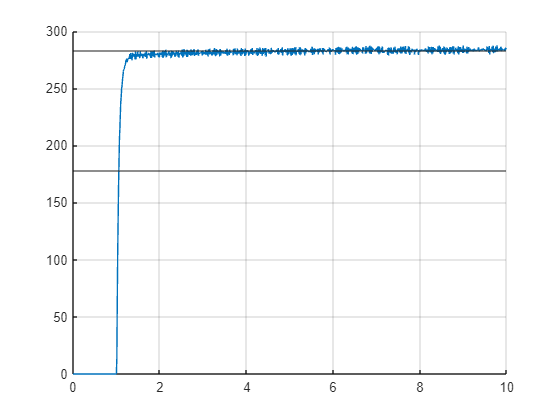


figure;
hold on;
plot(t,y);
yline(y_ss);
yline(y_ss_63);
grid on;


Tm1_positive = 1.057 - 1

Tm1_positive = 0.0570


% Negative step
load step_negative.mat

y_ss = mean(y( length(y)/2:length(y)))

y_ss = -289.3133

y_ss_63 = 0.63 * y_ss

y_ss_63 = -182.2674


figure;
hold on;
plot(t,y);
yline(y_ss);
yline(y_ss_63);
grid on;

Tm1_negative = 1.056 - 1

Tm1_negative = 0.0560


Tm1 = mean([Tm1_positive, Tm1_negative])

Tm1 = 0.0565


J = k_regr^2 * Tm1 / R_regr

J = 2.2219e-05


y_ss_predicted = V / k_regr

y_ss_predicted = 298.4195

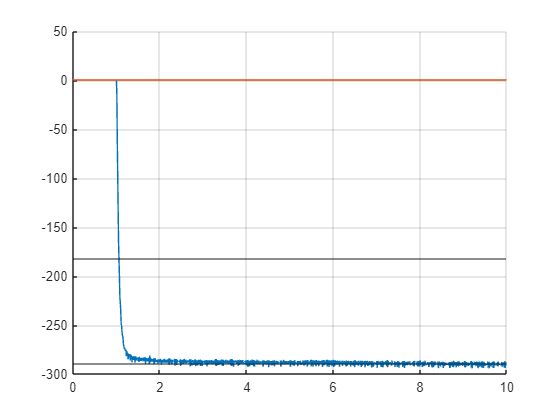

y_predicted = exp(-1/J * t);
plot(t, y_predicted)

% Save the data
R = R_regr;
L = 4.5e-3;
kphi = k_regr;
J = J;

save("estimated_parameters.mat", 'R', 'L', 'kphi', 'J')

m_load = 0.009;
l_load = 0.23;
J_load = 1/12*m_load*l_load^2 + m_load*((l_load - 0.04)/2)^2

J_load = 1.2090e-04

b = 0;
J_tot = J + J_load

J_tot = 1.4312e-04


% Second order model (Voltage -> Speed)
numSpeed = [kphi];
denSpeed = [L*J_tot, b*L+J*R, b*R+kphi^2];
sysSpeed = tf(numSpeed, denSpeed)

sysSpeed =
 
                 0.03328
  -------------------------------------
  6.44e-07 s^2 + 6.256e-05 s + 0.001107
 
Continuous-time transfer function.



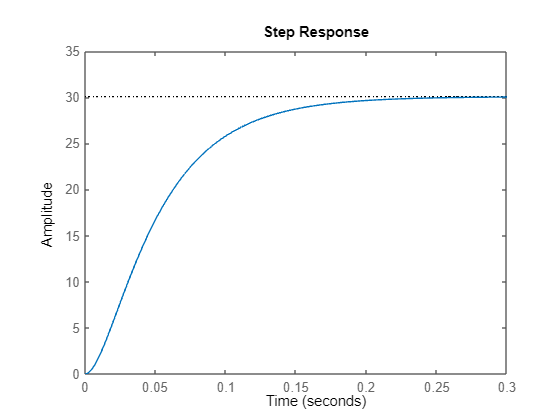

figure;
step(sysSpeed);

% Voltage -> Position
s = tf('s');
sysMot = 1/s * sysSpeed

sysMot =
 
                   0.03328
  -----------------------------------------
  6.44e-07 s^3 + 6.256e-05 s^2 + 0.001107 s
 
Continuous-time transfer function.



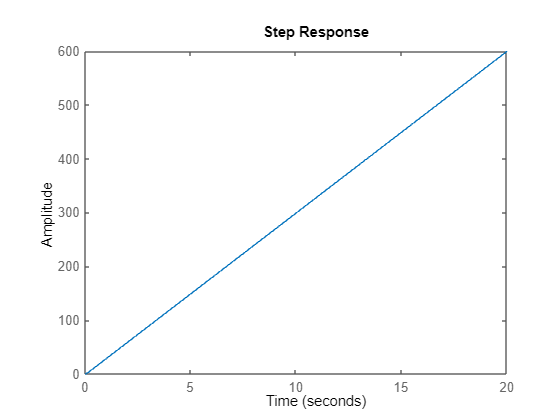

step(sysMot)